# Optimisation and Statistical Data Analysis

# Exercise Set 10 Solutions

Set the size of figures.

figure; set(gcf,'position',[0 0 500 300])

## Problem 1

The observations are 

sA=[11.23 14.36 8.33 10.50 23.42 9.15 14.47 6.47 12.40 19.38];
sB=[11.27 14.41 8.35 10.52 23.41 9.17 13.52 6.46 12.45 19.35];

Assuming the samples were the same for both devices, we can consider the *matched differences*:

y=sA-sB

y =    -0.0400   -0.0500   -0.0200   -0.0200    0.0100   -0.0200    0.9500    0.0100   -0.0500    0.0300


The default histogram indicates skewness: 

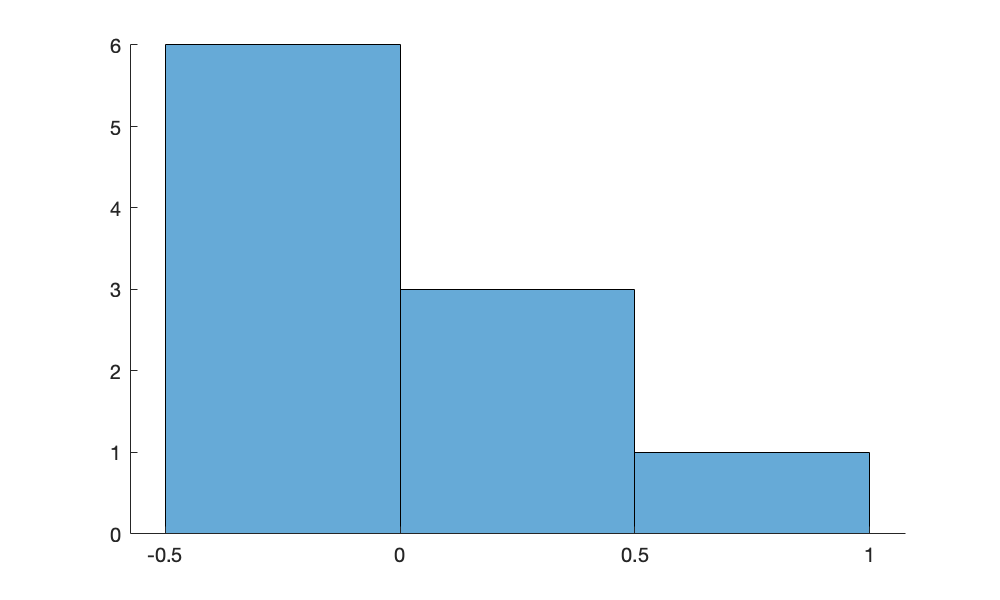

histogram(y), box off

However, the number of observations is small so this skewness might just be due to sampling variation. Let's go ahead and assume that the observed differences are conditionally independent with identical Gaussian distributions:

 
$$y_i\mid \mu,\sigma^2 \sim \text{norm}(\mu,\sigma)$$


With the default prior $p(\mu,\sigma^2)\propto \sigma^{-2}$, the posterior mean is

ybar=mean(y)

ybar = 0.0800

which is also the posterior median. We note that it is positive. But how strongly do we believe that systematic difference is positive?

The posterior 95% confidence interval is

n=length(y); 
s2=var(y); 
b=sqrt(s2/n); 
CI95=ybar+[-1,1]*b*tinv(0.975,n-1)

CI95 =    -0.1395    0.2995


The posterior confidence interval for $\mu$ contains both positive and negative values, so the belief that $\mu$ is positive (or negative) isn't strong. 

To make the confidence interval smaller one would need more observations. One would need about 100 independent observations to make the confidence interval 10 times smaller. 

To find the posterior probability that $\mu>0$, we use $z=\frac{\mu-\bar{y}}{b} \sim t_{n-1}$ and obtain


$$P(\mu>0) = 1-P(\mu\leq 0) = 1-P(bz+\bar{y} \leq 0) = 1-P(z \leq -\bar{y}/b)$$


1-tcdf(-ybar/b,n-1)

ans = 0.7845

which better than 50:50 but not very high. 

## Problem 2

### Part a

The observations are

y1=[22.0, 23.9, 20.9, 23.8, 25.0, 24.0, 21.7, 23.8, 22.8, 23.1];

These points lie fairly well in a straight line on a QQ plot, which indicates that the data is Gaussian.

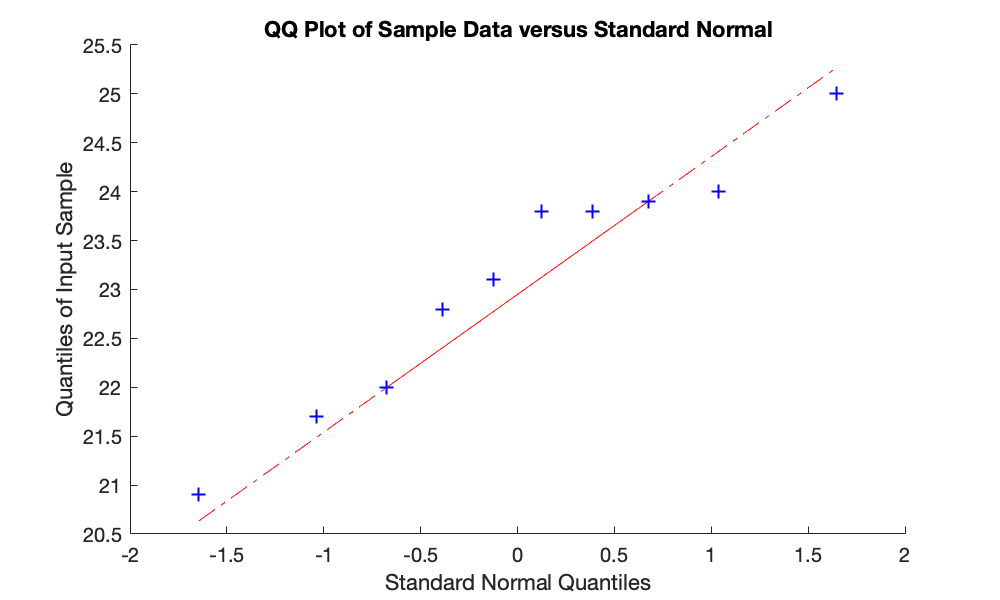

qqplot(y1)

### Part b

The posterior mean for "typical length" $\mu_1$ is

y1bar=mean(y1)

y1bar = 23.1000

which is also the posterior median. The  posterior is $\mu_1 \mid \text{data} \sim \bar{y_1}+b_1 z$ with $z\sim \text{t}_{n_1-1}$ and

n1=length(y);   
b1=sqrt(var(y1)/n1);

The 95% confidence interval is

CI95=y1bar+[-1,1]*b1*tinv(0.975,n1-1)

CI95 =    22.2033   23.9967


Plot the posterior density for $\mu$:

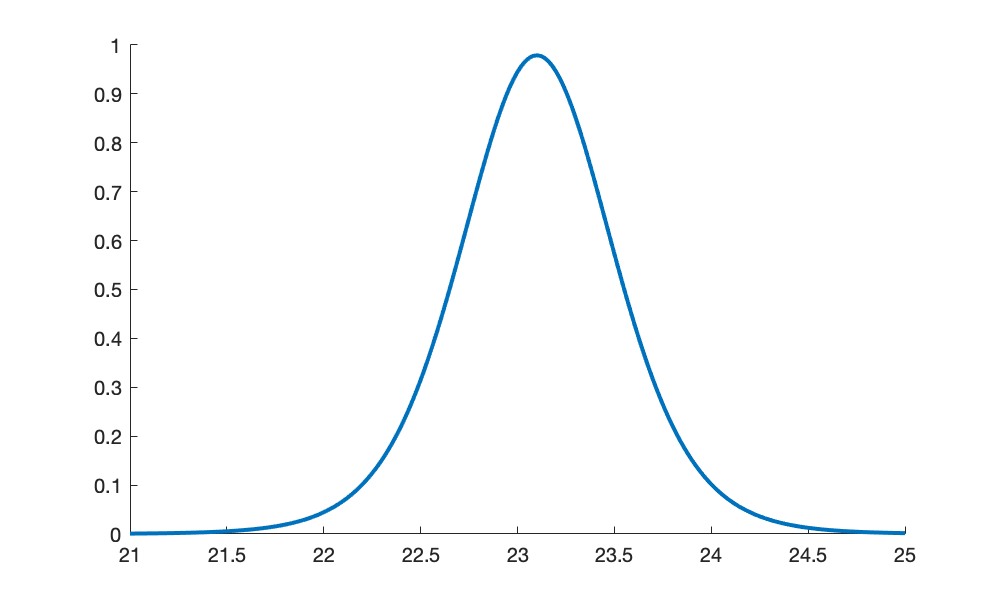

mu1=21:.02:25; 
p=tpdf((mu1-y1bar)/b1,n1-1)/b1;
plot(mu1,p,'linewidth',2), box off

### Part c

The density histogram and posterior predictive density agree fairly well, considering that the number of observations is rather small. 

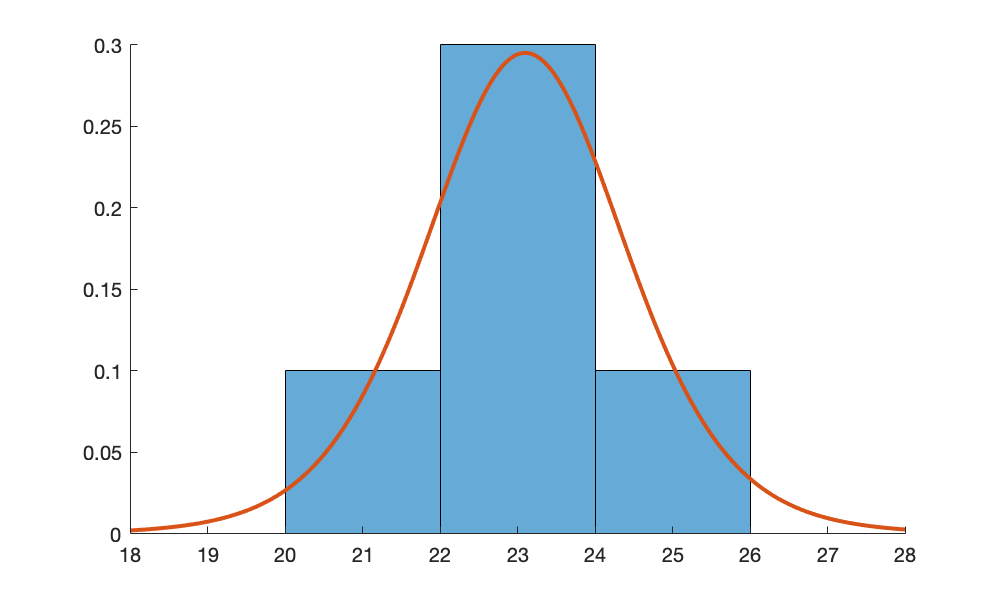

histogram(y1,'normalization','pdf'), box off
y1pred=18:.02:28;
b1pred=sqrt((1+1/n1)*var(y1)); 
ppred=tpdf((y1pred-y1bar)/b1pred,n1-1)/b1pred;
hold on, plot(y1pred,ppred,'linewidth',2), hold off

## Extra Problem (a)

For option (1) with three clocks, the precisions are updated using the one-at-a-time update formula as:

   
$$c_0=0$$
 

   
$$c_1=c_0+\frac{1}{10^2}=0.01$$


   
$$c_2=c_1+\frac{1}{10^2}=0.02$$


   
$$c_3=c_2+\frac{1}{10^2}=0.03$$


For option (1) with two clocks, the precisions are updated as:

   
$$c_0=0$$


   
$$c_1=c_0+\frac{1}{10^2}=0.01$$
 

   
$$c_2=c_1+\frac{1}{5^2}=0.05$$


Option (2) has greater precision (i.e. less variance). 

If model-B clock would cost as much as *five* new model-A clocks, then for the same budget we could have better overall precision ($c_6=0.06$) with six model-A clocks than with option (2). Thus it is possible that for the same budget, a precise but very expensive sensor can be outperformed by a large number of imprecise but cheap sensors. 

### Extra Problem (b)

The posterior predictive distribution of the difference $\tilde{y}$ is

  
$$\frac{\tilde{y}-\bar{y}}{s\sqrt{1+\frac{1}{n}}}  \mid \text{data} \sim t_{n-1}$$
 

and so the posterior probability that $\tilde{y}>0$ is 

1-tcdf(-ybar/sqrt((1+1/n)*s2),n-1)

ans = 0.5954

### Extra Problem (c)  

Enter the data

y2=[23.2 22.0 22.2 21.2 21.6 21.9 22.0 22.9 22.8];

Assuming a model similar to Problem 2, the posterior distribution for typical egg length in reed warbler nests is 


$$\mu_2\mid \text{data} \sim \bar{y_2}+b_2 z$$
 

with $z\sim \text{t}_{n_2-1}$ and

y2bar=mean(y2);
n2=length(y2);  
b2=sqrt(var(y2)/n2);

The posterior probablity of $\mu_1 > \mu_2$ is found by Monte Carlo simulation, as in slide 23 of lecture 9. 

N=1e4; rng('default');
L1=y1bar+b1*trnd(n1-1,1,N);      % samples of cuckoo eggs in dunnock nest 
L2=y2bar+b2*trnd(n2-1,1,N);   % samples of cuckoo eggs in reed warbler nest
prob=sum(L1>L2)/N

prob = 0.9618

Note that the observations are not *matched pairs* so one can't proceed as in Problem 1. 